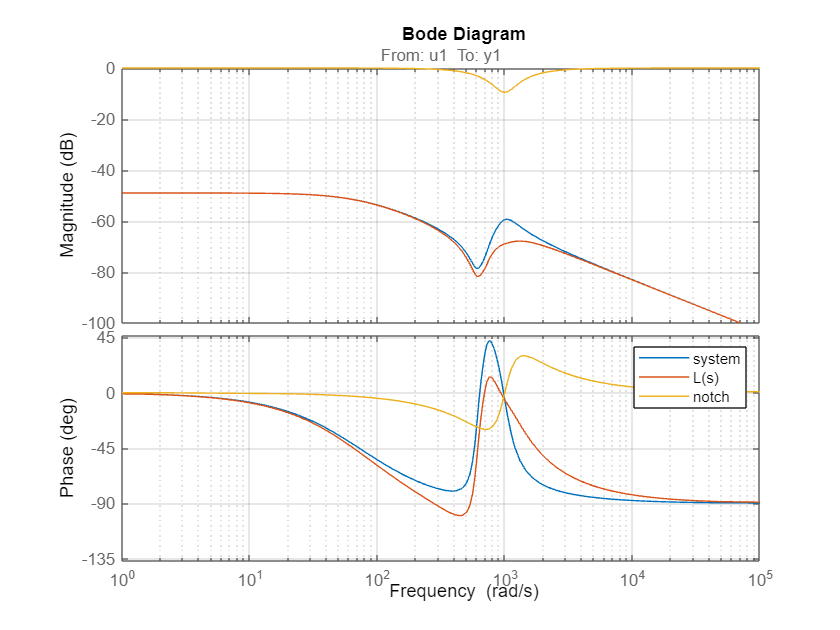

clear all
close all
clc
load ide_modelli_scara.mat

Gs1 = modello_continuo_q2;
tf(Gs1);
wn = 1000;
xci_z=0.2; %aggiustate xci_z e xci_p per rendere il filtro più o meno selettivo
xci_p=0.6;
s=tf('s');
notch=(s^2+2*xci_z*wn*s+wn^2)/(s^2+2*xci_p*wn*s+wn^2);
F = 1/(0.003*s+1);

P=Gs1*notch;

bode(Gs1)
hold on
bode(P)
bode(notch)
%bode(F)
hold off

grid on
legend('system','L(s)','notch')

wc = 300;
Kp=1/abs(freqresp(P,wc));

C=Kp

C = 1.5252e+03

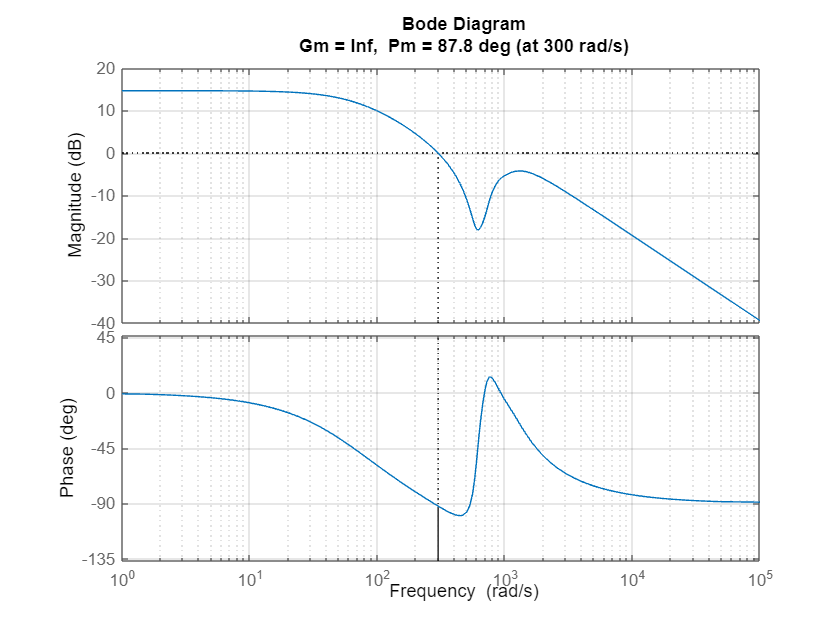

figure
margin(C*P)
grid on


loop1 = feedback(C*P,1);

loop1 =
 
  A = 
           x1      x2      x3      x4      x5      x6      x7
   x1  -176.7   858.2  -61.76   223.5    -251  -173.9       0
   x2   -1346  -457.4   188.2  -518.1   583.2   319.5       0
   x3   3.395   14.17  -100.5   605.7  -26.56  -18.21       0
   x4  -7.679  -33.18    -822  -112.7   77.26   42.67       0
   x5   294.1    1264  -468.2   664.3  -902.1   -1621       0
   x6   145.2   623.8  -231.1   327.9  -408.9   -1200  -976.6
   x7       0       0       0       0       0    1024       0
 
  B = 
           u1
   x1   6.958
   x2  -12.78
   x3  0.7286
   x4  -1.707
   x5   64.83
   x6      32
   x7       0
 
  C = 
           x1      x2      x3      x4      x5      x6      x7
   y1  -4.537  -19.49   7.222  -10.25   12.78       0       0
 
  D = 
       u1
   y1   0
 
Continuous-time state-space model.


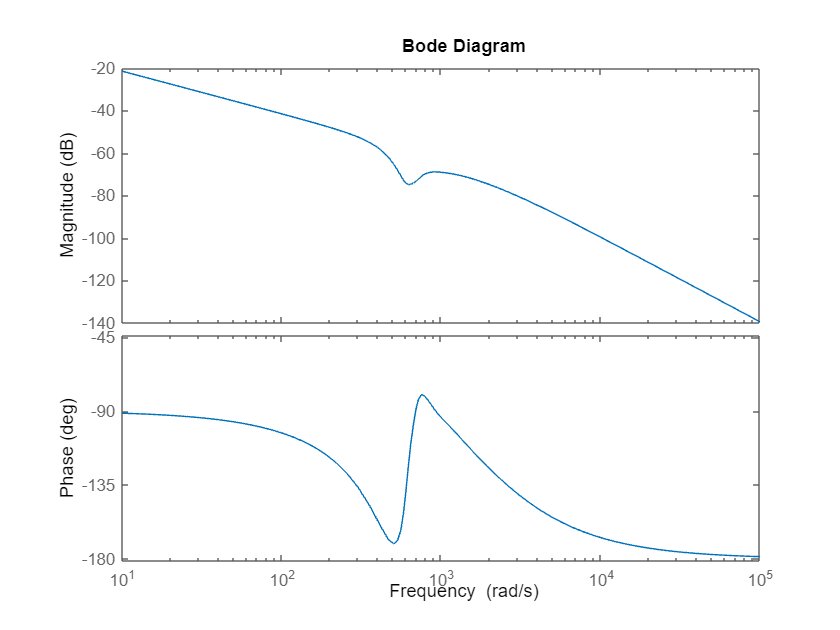

G1 = loop1*1/s;
bode(G1)

% tf(G1)


% wc_des=200;
% J=@(x)pivel_cost_function(x,G1,wc_des);
% MS=1.4;
% wh=2000;
% Fh_max=0.1;
% wl=0.1;
% Dh_max=0.1;%disturbo sul carico ridotto di almeno 10 volte
% 
% w_vector=logspace(-3,3)'; % [10^-3,10^3]
% w_vector=sort([w_vector;wl;wh]);

%nlcon=@(x)pivel_constraints(x,G1,w_vector,MS,wh,Fh_max,wl,Dh_max);%anonious function

Risolvo il problema con fmincon, la soluzione è locale.

Impongo che $K_p\in[0.01,10000]$ e $K_i\in[0.01,10000]$

%x0=[1,0.1];% scegliere un punto di partenza meglio provarne di diversi
%x=fmincon(J,x0,[],[],[],[],[0.001 0.000001],[10000 10000],nlcon)
%Kp=x(1);
%Ki=x(2);
%C1=tf([Kp Ki],[1 0])
%margin(C1*G1)
%step(feedback(C1*G1,1))
